# Trial 1: Asymptotic Efficiency under Repeated Measurement 

clear;
close all;
clc;

## 1. Settings

### 1.1 enviroment settings

%set room size, robot size, and the true pose
Room_Length=50; Room_Width=50;
Robot_Size=10;
theta=60; R=[cosd(theta),-sind(theta);sind(theta),cosd(theta)];
t=[0;25];

### 1.2 simulation settings

T=[1,10,100,1000,10000,100000,1000000,10000000]; %number T of repeated ranging
sigma=0.05*[1,2,3,4,5,6];%Standard Deviations
L=5;                   %Monte-Carlo rounds
%matrix to store simulation results
%ULS
Y0_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%GN-ULS
Ye_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t

%vector to store computation time
time_0=zeros(length(T),1);
time_e=zeros(length(T),1);

## 2. For different number T of repeated ranging

for o=1:length(T)
    M=3; % M*T(o) anchors
    N=2; % N tags
    [A,S,Mt]=setting(T(o),Room_Length,Room_Width,Robot_Size,M,N);

    %mse
    mse_R0_c=0; mse_R0_a=0; mse_t0=0;
    mse_Re_c=0; mse_Re_a=0; mse_te=0;

    %true distance
    Sa=R*S+t; %tags' coordinate in global frame
    relative_position=zeros(2,Mt*N);
    for i=1:N %for every tag i=1,...,N
        relative_position(:,(i-1)*Mt+1:i*Mt)=A-Sa(:,i);
    end
    relative_distance=vecnorm(relative_position)'; %(Mt*N,1)
    
    Sigma=zeros(1,Mt*N); %standard deviations
    for i=1:N
        Sigma((i-1)*Mt+1:i*Mt)=repmat(sigma((i-1)*M+1:i*M),1,T(o));
    end

#### ULS- precalculation    

    tic
    A_bar=A-(A*ones(Mt,1))*ones(1,Mt)/Mt;
    Psi=[0,1;1,0;-1,0;0,1];%(4,2)
    H1=-2*kron(S',A_bar')*Psi;    %(N*Mt,2)
    H2=repmat(-2*A_bar',N,1); %(N*Mt,2)
    H=[H1,H2];       %(N*Mt,4)
    HtH_invHt=(H'*H)\H';
    time_0(o)=time_0(o)+toc;

### 2.1 Monte-Carlo Runs 

    for l=1:L
        d=relative_distance+Sigma'.*randn(Mt*N,1); %(Mt*N,1) distance measurements corrupted by Gaussian noises
        d_square=d.^2;

        %ULS
        tic;
        D=d_square-(vecnorm(repmat(A,1,N))').^2-(Sigma').^2;
        %projection
        for i=1:N
            D_bar((i-1)*Mt+1:i*Mt,:)= D((i-1)*Mt+1:i*Mt,:)-ones(Mt,1)*(ones(1,Mt)*D((i-1)*Mt+1:i*Mt,:))/Mt;
        end
        [R0,t0]= ULS(D_bar,HtH_invHt);
        time_0(o)=time_0(o)+toc/L;

        %GN-ULS
        tic;
        [Re,te] = Gauss_Newton(R0,t0,A,S,d,Sigma);
        time_e(o)=time_e(o)+toc/L;

        %MSE
        %ULS
        mse_R0_c=mse_R0_c+norm(R0-R,'fro')^2;
        mse_R0_a=mse_R0_a+angular_distance(R0,R)^2;
        mse_t0=mse_t0+norm(t0-t)^2;
        %GN-UCLS
        mse_Re_c=mse_Re_c+norm(Re-R,'fro')^2;
        mse_Re_a=mse_Re_a+angular_distance(Re,R)^2;
        mse_te=mse_te+norm(te-t)^2;
        if mode(l,10)==0 %iteration tracking
            l
        end
    end
    time_e(o)=time_e(o)+time_0(o);

### 2.2 RMSE

    %ULS
    Y0_r(o,1)=sqrt(mse_R0_c/L);
    Y0_r(o,2)=sqrt(mse_R0_a/L);
    Y0_r(o,3)=sqrt(mse_t0/L);
    %GN-ULS
    Ye_r(o,1)=sqrt(mse_Re_c/L);
    Ye_r(o,2)=sqrt(mse_Re_a/L);
    Ye_r(o,3)=sqrt(mse_te/L);

### 2.3 Constrained Cramer Rao Lower Bound

    o
end

o = 1

o = 2

o = 3

o = 4

o = 5

o = 6

o = 7

o = 8

% save('Trial1_plot.mat','T','Y0_r','Ye_r','Ym_r','Y1_r','Y2_r','CRLB','time_0','time_e','time_m','time_1','time_2')

## 3. Plot

### 3.1 RMSE and number T of repeated ranging

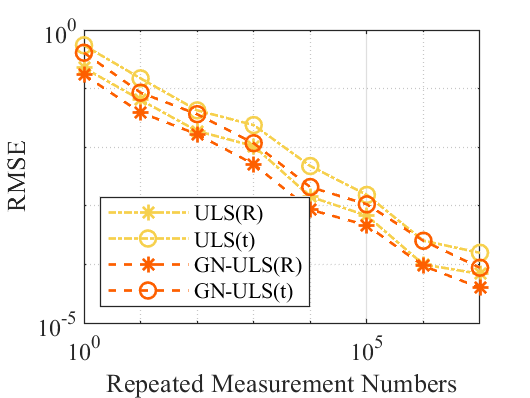

figure(1)
%ULS
loglog(T,Y0_r(:,1),'-.*','LineWidth',1,'MarkerSize',6,'Color','#f6d04d');
hold on
loglog(T,Y0_r(:,3),'-.o','LineWidth',1,'MarkerSize',6,'Color','#f6d04d');
hold on
%GN-ULS
loglog(T,Ye_r(:,1),'--*','LineWidth',1,'MarkerSize',6,'Color','#fd5f00');
hold on
loglog(T,Ye_r(:,3),'--o','LineWidth',1,'MarkerSize',6,'Color','#fd5f00');
hold on

set(gca,'Fontname', 'Times New Roman')
xlabel('Repeated Measurement Numbers')
ylabel('RMSE')
legend({'ULS(R)','ULS(t)','GN-ULS(R)','GN-ULS(t)'}, 'Location','southwest')
grid on

### 3.2 computation time for different methods

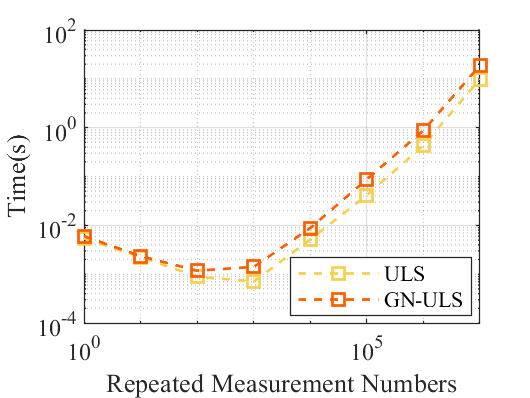

figure(3)
%ULS
loglog(T,time_0,'--s','LineWidth',1,'MarkerSize',6,'Color','#f6d04d');
hold on
%GN-ULS
loglog(T,time_e,'--s','LineWidth',1,'MarkerSize',6,'Color','#fd5f00');
hold on
set(gca,'Fontname', 'Times New Roman')
xlabel('Repeated Measurement Numbers')
ylabel('Time(s)')
legend( 'ULS','GN-ULS','Location','Best')
grid on

save('time_GNULS.mat','time_e','time_0')